clc
clear
image = imread("Images/DB1/db1_06.jpg");

%Path
addpath(genpath("facefunctions"));
addpath(genpath("eigenfacefunctions"));

%imshow(image)

%image format
image = whiteworld(image);
image = im2uint8(image);

%Chrominance Eye map
eyeMapC = eyemapC(image);

%Luminance Eye map
eyeMapL = eyemapL(image);

%Combined eye map
    % Eye Map L + C
    eyeMapFinal = imfuse(eyeMapL, eyeMapC, 'blend');

    %Strucute element based on height
    SE_height = round(length(image(:,1))/36);
    SE = strel('disk',SE_height,8);

    %Final dilute
    eyeMapFinal = imdilate(eyeMapFinal, SE);

    % Normalizing the final eye map between 0 and 255
    eyeMapFinal = uint8(im2gray(eyeMapFinal));

    % Threshold to create binary image
    eyeMapFinal = (eyeMapFinal >= 170);
    BW = logical(eyeMapFinal);

    %imshow(BW)



%Remove sections of eye map based on mouth position
[~, mouthPos] = mouthmap(image)

mouthPos =   173.4023  355.2018


mouthX = round(mouthPos(1));
mouthY = round(mouthPos(2));

[rows, cols] = size(image(:,:,1))

rows = 475

cols = 362

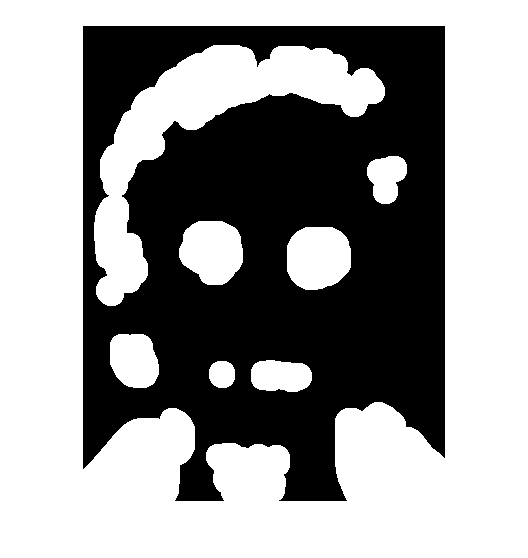


%Only remove as long as 2 regions remain
    imshow(BW)

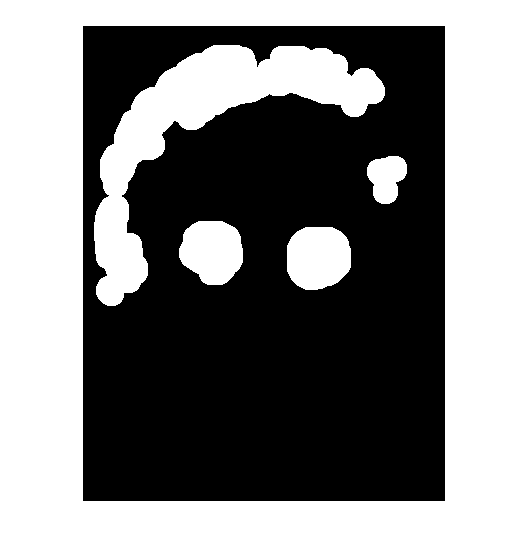

    %Remove bottom
    BW_new = BW;
    BW_new( mouthY - round((1/8)*rows) : rows , : ) = 0; % bottom
    if size(regionprops(BW_new, "area"),1) >= 2
        BW = BW_new;
    end
    imshow(BW)

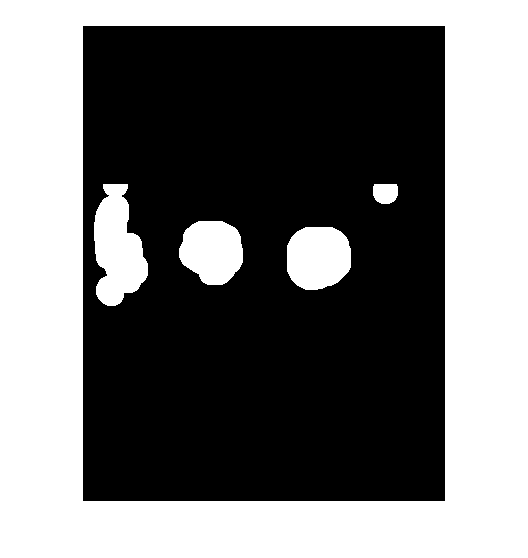

        
    %Remove top
    BW_new = BW;
    BW_new( 1 : round((1/3.0)*rows), :) = 0;                  % top
    if size(regionprops(BW_new, "area"),1) >= 2
        BW = BW_new;
    end
    imshow(BW)

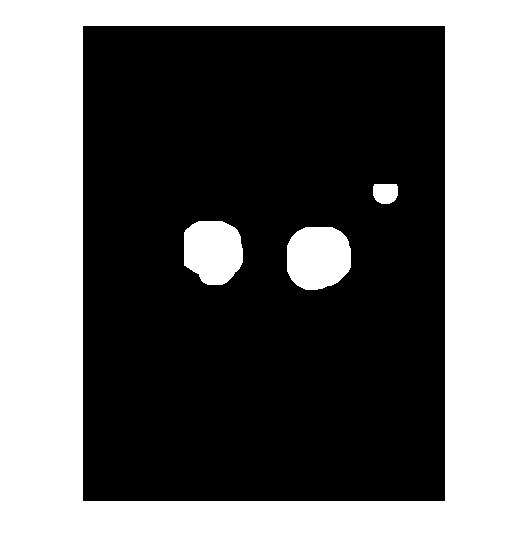

        
    %Remove left
    BW_new = BW;
    BW_new( : , 1 : mouthX - round((1/5)*cols) ) = 0;    % left
    if size(regionprops(BW_new, "area"),1) >= 2
        BW = BW_new;
    end
    imshow(BW)

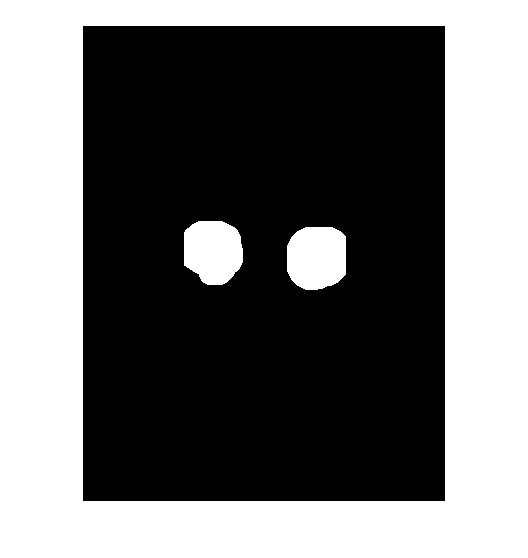


    %Remove bottom
    BW_new = BW;
    BW_new( : , mouthX + round((1/4)*cols) : cols ) = 0; % right
    if size(regionprops(BW_new, "area"),1) >= 2
        BW = BW_new;
    end
    imshow(BW)



    eyemap = BW;
    
    mm = bwareafilt(eyemap,2); % Selecting 2 largest object of image
    % Calculates the center of each object
    labeledImage = logical(mm);
    measurements = regionprops(labeledImage, mm, 'Centroid');
    [a, ~] = size(measurements)

a = 2

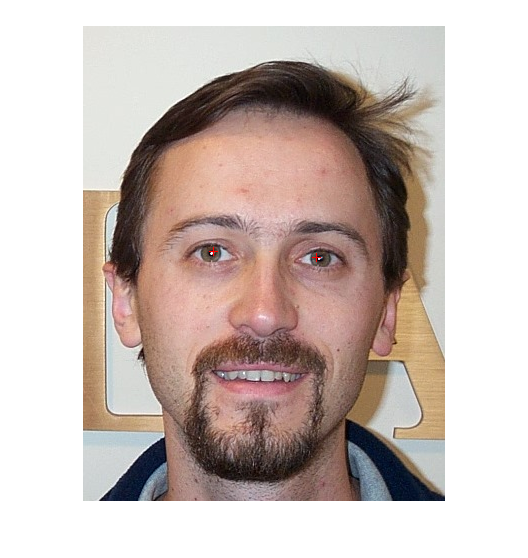

    
    % If two centriods are found, they become the eye positions 
    if(a == 2)
        centroid1 = measurements(1).Centroid;
        centroid2 = measurements(2).Centroid;

        centroid1 = round(centroid1);
        centroid2 = round(centroid2);

        mm(centroid1(2),centroid1(1),:) = 0;
        mm(centroid2(2),centroid2(1),:) = 0;

        eye1 = centroid1;
        eye2 = centroid2;
        numberOfEyes = 2;
        
    else 
        if(a == 1) 
            eye1 = [];              % If there is only one centroid found, eye positions are not set 
            eye2 = [];              % and number of eyes are set to one.
            numberOfEyes = 1;
            
        else
            eye1 = [];              % If there is less than one centroid, eye positions are are also not set
            eye2 = [];              % and number of eyes are set to zero
            numberOfEyes = 0;        
            
        end

    end

if numberOfEyes == 2
    imshow(image)
    hold on
    plot(eye1(1), eye1(2), "r+")
    plot(eye2(1), eye2(2), "r+")
    hold off
end


%TEST IF EXTRA TIME

% test = regionprops(BW)
% [B,L,N] = bwboundaries(BW)
% imshow(L)
% %Remove close to edge
% centerPosition = round(size(image(:,:,1))./2)
% 
% [rows, cols] = size(image(:,:,1))
% for k = 1:N
%     boundary = B{k};
% 
%     right = cols - max(boundary(:,2))
%     left = min(boundary(:,2))
% 
%     top = max(boundary(:,2))
%     bot = rows - min(boundary(:,2))
%     
% end